# Lab - 03

format long e

Question - 1

n = 5;

% forming a positive definite matrix A
a = 2; b = 4;
r = a + (b - a).*rand(n,1); D = diag(r);
B = randn(n); [Q,R] = qr(B);

A = Q'*D*Q;
G = mychol(A);
G_hat = chol(A);
norm_diff = norm(G - G_hat);

disp('The positive definite matrix to be used - '); disp(A);

The positive definite matrix to be used - 
     2.483906296834732e+00    -2.037671172935567e-01    -2.869683295863988e-01     5.130327659459412e-02     6.310797550667105e-02
    -2.037671172935568e-01     3.084146090342716e+00     5.476403417731084e-01     2.235703139207238e-01     3.596679257619211e-02
    -2.869683295863988e-01     5.476403417731084e-01     3.030274409383425e+00     3.561468178729443e-01    -1.807605156580293e-01
     5.130327659459424e-02     2.235703139207240e-01     3.561468178729443e-01     2.864187259200428e+00     4.291606332055056e-01
     6.310797550667106e-02     3.596679257619206e-02    -1.807605156580293e-01     4.291606332055055e-01     2.718562213975444e+00



disp('The cholesky factor calculated by mychol(A) - '); disp(G);

The cholesky factor calculated by mychol(A) - 
     1.576041337286155e+00    -1.292904649597776e-01    -1.820817276788821e-01     3.255198666485180e-02     4.004208139320702e-02
                         0     1.751408023852009e+00     2.992443242255646e-01     1.300547743928994e-01     2.349187130420140e-02
                         0                         0     1.705160839407146e+00     1.895163079637136e-01    -1.058547611931270e-01
                         0                         0                         0     1.676394032451206e+00     2.653690891243832e-01
                         0                         0                         0                         0     1.623200848245778e+00



disp('The cholesky factor calculated by inbuilt chol(A) - '); disp(G_hat);

The cholesky factor calculated by inbuilt chol(A) - 
     1.576041337286155e+00    -1.292904649597776e-01    -1.820817276788821e-01     3.255198666485180e-02     4.004208139320702e-02
                         0     1.751408023852009e+00     2.992443242255646e-01     1.300547743928994e-01     2.349187130420140e-02
                         0                         0     1.705160839407146e+00     1.895163079637136e-01    -1.058547611931270e-01
                         0                         0                         0     1.676394032451206e+00     2.653690891243832e-01
                         0                         0                         0                         0     1.623200848245778e+00



disp('The norm of difference between G and G_hat - '); disp(norm_diff);

The norm of difference between G and G_hat - 
     0



Question - 2

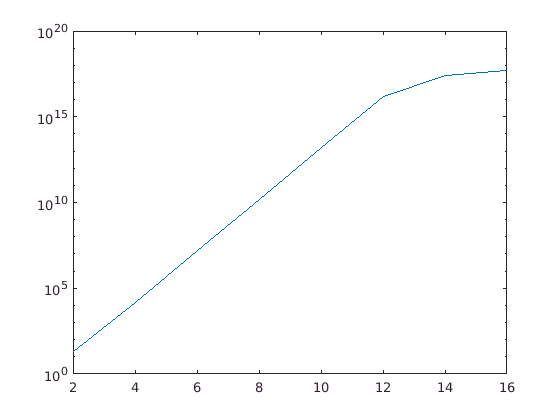

% 2 - Norm
C=[];
N= 2:2:16;
for n=N
    H=hilb(n); C = [C; cond(H)];
end
semilogy(N,C);

% 1 - Norm
C=[];
N= 2:2:16;
for n=N
    H=hilb(n); C = [C; cond(H, 1)];
end

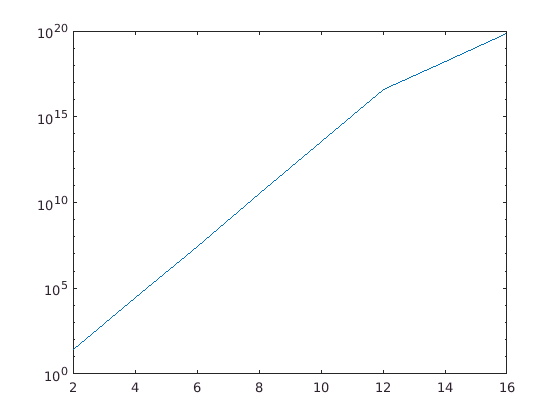

semilogy(N,C);

% inf - Norm
C=[];
N= 2:2:16;
for n=N
    H=hilb(n); C = [C; cond(H, inf)];
end

semilogy(N,C)

## Functions

function G = mychol(A)
    [n,~] = size(A);
    G = zeros(n,n);
    g11 = sqrt(A(1,1));
    G(1,1) = g11;
    
    if n == 1
        return;
    end
    b = A(1, 2:n)';
    A_hat = A(2:n, 2:n);
    
    g = b ./ g11;
    G(1, 2:n) = g;
    G(2:n, 2:n) = mychol(A_hat - g*g');
end